% Initialising variables
load example_1.mat
A = sparse(adjacency_matrix);
n = size(A, 1);
e = ones(n, 1);
alpha = 0.85;
v = e/n;
iterations = 50;

% Verifying pagerank vector
optimized_p = pagerank(A, alpha, v, iterations)

optimized_p =     0.0836
    0.1125
    0.1013
    0.0877
    0.0446
    0.2938
    0.2766


unoptimized_p = pagerank_full(A, alpha, v, iterations)

H =    (2,1)        1
   (3,1)        1
   (4,1)        1
   (5,1)        1
   (1,2)        1
   (3,2)        1
   (6,2)        1
   (2,3)        1
   (4,3)        1
   (1,4)        1
   (2,4)        1
   (3,4)        1
   (7,6)        1
   (6,7)        1


e_H =      1     1     1     1     0     1     1


S =          0    0.3333         0    0.3333    0.1429         0         0
    0.2500         0    0.5000    0.3333    0.1429         0         0
    0.2500    0.3333         0    0.3333    0.1429         0         0
    0.2500         0    0.5000         0    0.1429         0         0
    0.2500         0         0         0    0.1429         0         0
         0    0.3333         0         0    0.1429         0    1.0000
         0         0         0         0    0.1429    1.0000         0


e_S =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


G =     0.0214    0.3048    0.0214    0.3048    0.1429    0.0214    0.0214
    0.2339    0.0214    0.4464    0.3048    0.1429    0.0214    0.0214
    0.2339    0.3048    0.0214    0.3048    0.1429    0.0214    0.0214
    0.2339    0.0214    0.4464    0.0214    0.1429    0.0214    0.0214
    0.2339    0.0214    0.0214    0.0214    0.1429    0.0214    0.0214
    0.0214    0.3048    0.0214    0.0214    0.1429    0.0214    0.8714
    0.0214    0.0214    0.0214    0.0214    0.1429    0.8714    0.0214


e_G =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


p =     0.0836
    0.1125
    0.1013
    0.0877
    0.0446
    0.2938
    0.2766


unoptimized_p =     0.0836
    0.1125
    0.1013
    0.0877
    0.0446
    0.2938
    0.2766


matlabs_p = centrality(digraph(A'), "pagerank", "FollowProbability", alpha)

matlabs_p =     0.0836
    0.1125
    0.1013
    0.0877
    0.0446
    0.2938
    0.2766


% Time of different algorithms
optimized = @() pagerank(A, alpha, v, iterations);
unoptimized = @() pagerank_full(A, alpha, v, iterations);
matlabs = @() centrality(digraph(A'), "pagerank", "FollowProbability", alpha);
optimized_t = timeit(optimized)

optimized_t = 8.2889e-04

% unoptimized_t = timeit(unoptimized)
matlabs_t = timeit(matlabs)

matlabs_t = 8.0429e-04

% Testing how sensitivity changes wrt alpha parameter
sensitivity = norm(pr_alpha_sensitivity(A, alpha, v))

sensitivity = 1.1131

alpha_values = [.1:.01:.99]

alpha_values =     0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000    0.5100    0.5200    0.5300    0.5400    0.5500    0.5600    0.5700    0.5800    0.5900


sensitivities = []


sensitivities =

     []



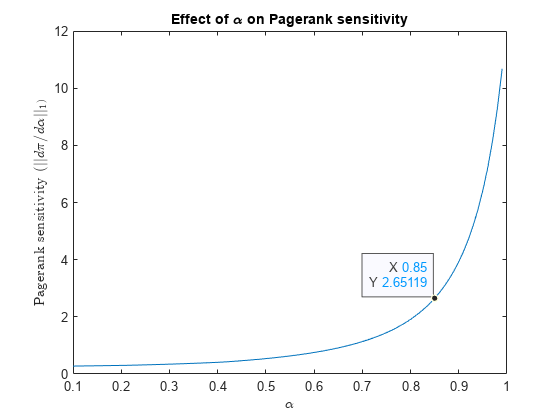

for i = 1:numel(alpha_values)
    sensitivities(end + 1) = norm(pr_alpha_sensitivity(A, alpha_values(i), v), 1);
end
plot(alpha_values, sensitivities);
xlabel("$$\alpha$$", "Interpreter","latex");
ylabel("Pagerank sensitivity ($$|| d \pi / d \alpha||_1$$)", "Interpreter","latex");
title("Effect of \alpha on Pagerank sensitivity")
saveas(gcf, "example_graph_sensitivity_plot", "png")

ax = gca;
chart = ax.Children(1);
datatip(chart,0.85,2.651);